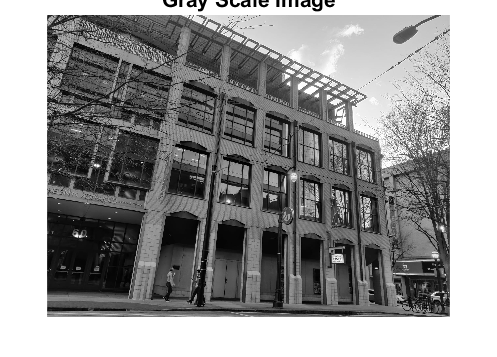

% Performing canny edge detection on the entire image of GSU - Aderhold Building
I = rgb2gray(imread("C:\Users\aswin\Desktop\CV\Assignment 2\Image_1.jpeg"));
imshow(I);
title("Gray Scale Image");

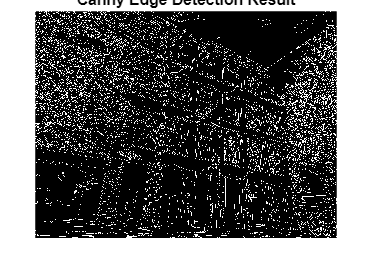

N = edge(I, 'Canny');
imshow(N);
title("Canny Edge Detection Result");

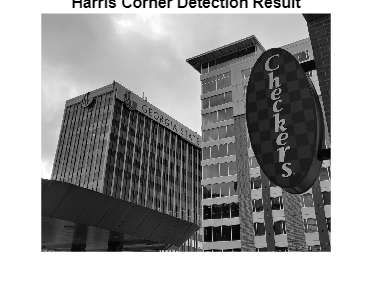

% Performing Harris Corner detection on the entire image of 90 Auburn Ave
% at GSU
H_image = rgb2gray(imread("C:\Users\aswin\Desktop\CV\Assignment 2\Image2.jpeg"));
imshow(H_image)
corners1 = detectHarrisFeatures(H_image);
title("Harris Corner Detection Result");

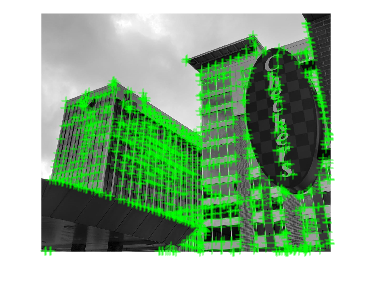

imshow(H_image); hold on;
plot(corners1);

corners1

corners1 =   1377×1 cornerPoints array with properties:

    Location: [1377×2 single]
      Metric: [1377×1 single]
       Count: 1377


% Identifying the Patches of Image 1 from Line #2
imSz = size(I);
patchSz = [5 5];
xIdxs = [1:patchSz(2):imSz(2) imSz(2)+1];
yIdxs = [1:patchSz(1):imSz(1) imSz(1)+1];
patches = cell(length(yIdxs)-1,length(xIdxs)-1);
for i = 1:length(yIdxs)-1
    Isub = I(yIdxs(i):yIdxs(i+1)-1,:);
    for j = 1:length(xIdxs)-1
        patches{i,j} = Isub(:,xIdxs(j):xIdxs(j+1)-1);
    end
end

% Selecting a region of the image - Patch{20,3} and performing HCD
N=figure, imagesc(patches{20,3})

N =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


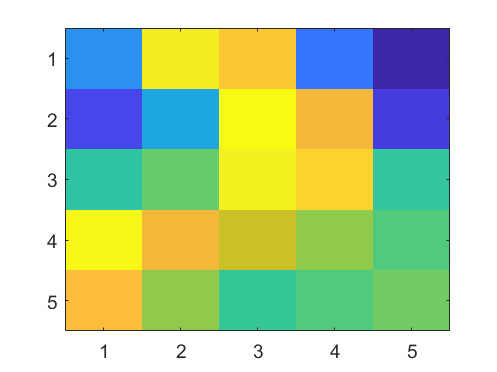

F = getframe(N);

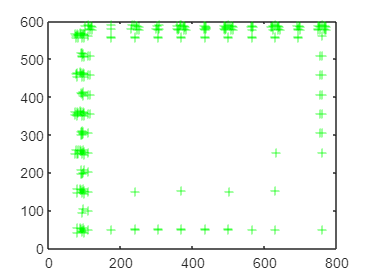

[X, Map] = frame2im(F);
X_image = rgb2gray(X);
corners_2 = detectHarrisFeatures(X_image);
plot(corners_2);

% Selecting a region of the image - Patch{13,30} and performing CED
P=figure, imagesc(patches{13,30})

P =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


P

P =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


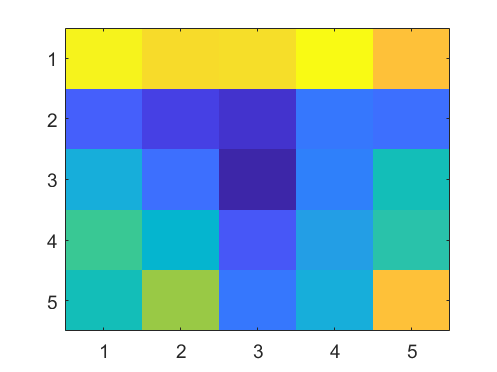

T = getframe(P);

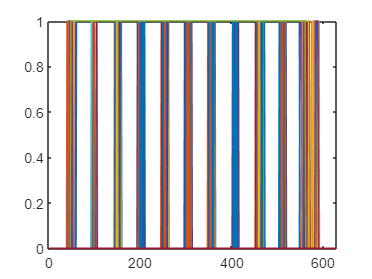

[S, Map] = frame2im(T);
S_image = rgb2gray(S);
N_2 = edge(S_image, 'Canny');
plot(N_2);

% Load images.
buildingDir = fullfile(toolboxdir('vision'),'visiondata','building');
%buildingScene = imageDatastore(buildingDir);








